# 3-Stimulus oddball paradigm

The goal of this short project is to process, analyze and interpret the EEG of a single healthy subject who performed a 3-stimulus oddball task. 		

The classical 2-stimulus oddball task consists in presenting repeatedly two different stimuli in a random sequence: one stimulus, called standard, occurs frequently, while the other stimulus occurs infrequently and is called target since the subject is instructed to respond in some way to this rare stimulus. The 3-stimulus oddball task is a modification of the 2-stimulus task where a third stimulus is added, occurring infrequently as the target stimulus, and called distractor. In this case too, the subject has to respond only to the target stimulus. In the specific 3-stimulus auditory oddball task, the standard stimulus was a 440 Hz sinusoidal tone (70% of trials), the target stimulus was a 660 Hz sinusoidal tone (15% of trials) and the distractor (15% of trials) was a naturalistic sound. Each stimulus lasted 200 ms. The subject was instructed to mentally count the target stimuli and ignoring the standard and distractor stimuli

### Data loading

clc; clear
load('sub-003_ses-01_task-Rest_eeg_original.mat')
X = double(X);
fs = srate;
path_locsfile='/Users/marcellosicbaldi/eeglab2021.1/sample_locs/Standard-10-20-Cap81.locs';
default_locs = readlocs(path_locsfile); %read the coordinates of 

readlocs(): 'loc' format assumed from file extension


%electrode locations made available by EEGLAB for 81 electrodes
ch_names_in_locs={default_locs(:).labels};
idx=zeros(1,length(ch_names));
for i=1:length(ch_names)
    idx(i)=find(strcmp(ch_names_in_locs,ch_names{i}));
end
locs = default_locs(idx); % memorize in locs the coordinates of the 59 electrodes of the present dataset

### Preprocessing 1

#### Resample

Done to reduce the computational cost of the following pre-processing steps.

I half the sampling rate --> My new data contains half of the samples --> I need also to half the time samples of the markers 

Matlab function ***resample***: automatically applies an antialiasing (LP) filter. Why? The sampling frequency must always be at least twice the maximum frequency of interest (Shannon theorem) --> I have to attenuate the frequencies components above half the new sampl freq. (Above 250 Hz in this case).

X_res = resample(X',1,2); % X_res contains half the samples of X
X_res = X_res';
fs = fs/2;
stim_samples = floor(stim_samples/2);

% Size of X and time vector
[n,m] = size(X_res);
X_samples = 1:m;
t = X_samples/fs;

#### Detrend

Done to remove possible slow linear drifts, due to noise originating at the electrode-gel interface.

It removes from the data the line that best fits the data in the least square sense.

X_det = detrend(X_res');
X_det = X_det';

#### Plot 

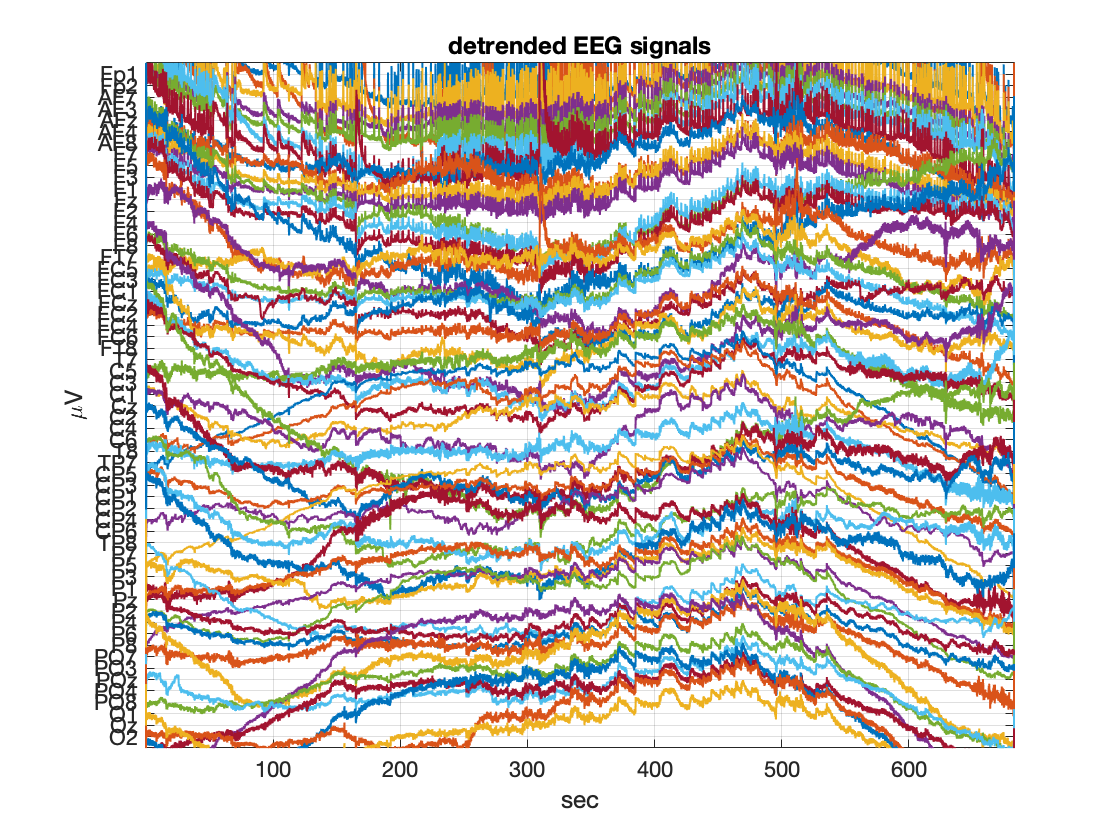

delta = 100;
X_samples = 1:m;
t = X_samples/fs; % time vector 
figure % entire duration
for i = 1:n
    plot(t, X_det(i,:)-delta*(i-1),'linewidth',1);
    hold on
end
xlim([t(1) t(end)])
ylim([-delta*n delta])
xlabel('sec')
ylabel('\muV')
title('detrended EEG signals')
set(gca,'ytick',[-delta*(n-1):delta:0])
set(gca,'ytickLabel',fliplr(ch_names))
set(gca,'fontsize',11)
grid

#### Filtering

Band-pass filtering [0.5 - 50] Hz with IIR elliptic filter 

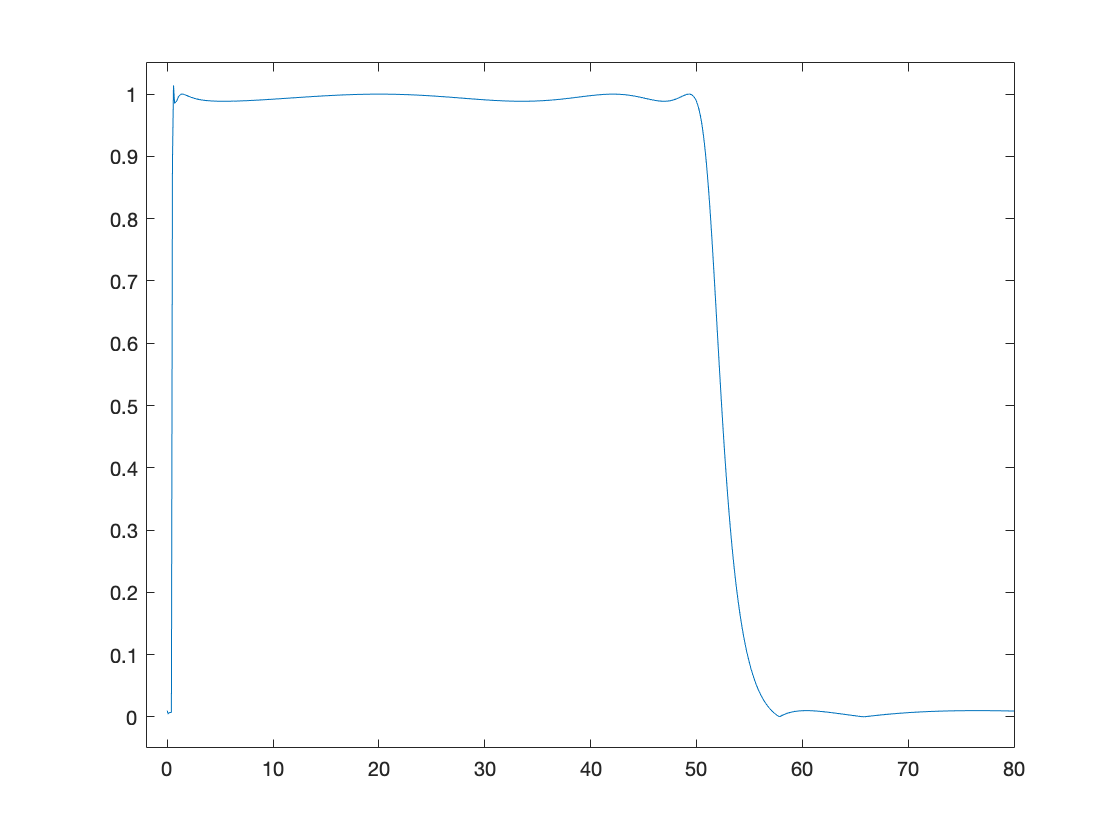

Wp = [0.5 50]/(fs/2); 
Ws = [0.1 60]/(fs/2);
Rp = 0.1; Rs = 40;
[N,Wp] = ellipord(Wp,Ws,Rp,Rs);      
[b,a] = ellip(N,Rp,Rs,Wp);
[H, F] = freqz(b,a,1251,fs);
figure
plot(F, abs(H))
xlim([-2 80])
ylim([-0.05 1.05])

X_filt = filtfilt(b,a,X_det')'; %with filtfilt is a zero-phase filter;

Plotting the filtered signals together with the stimuli times

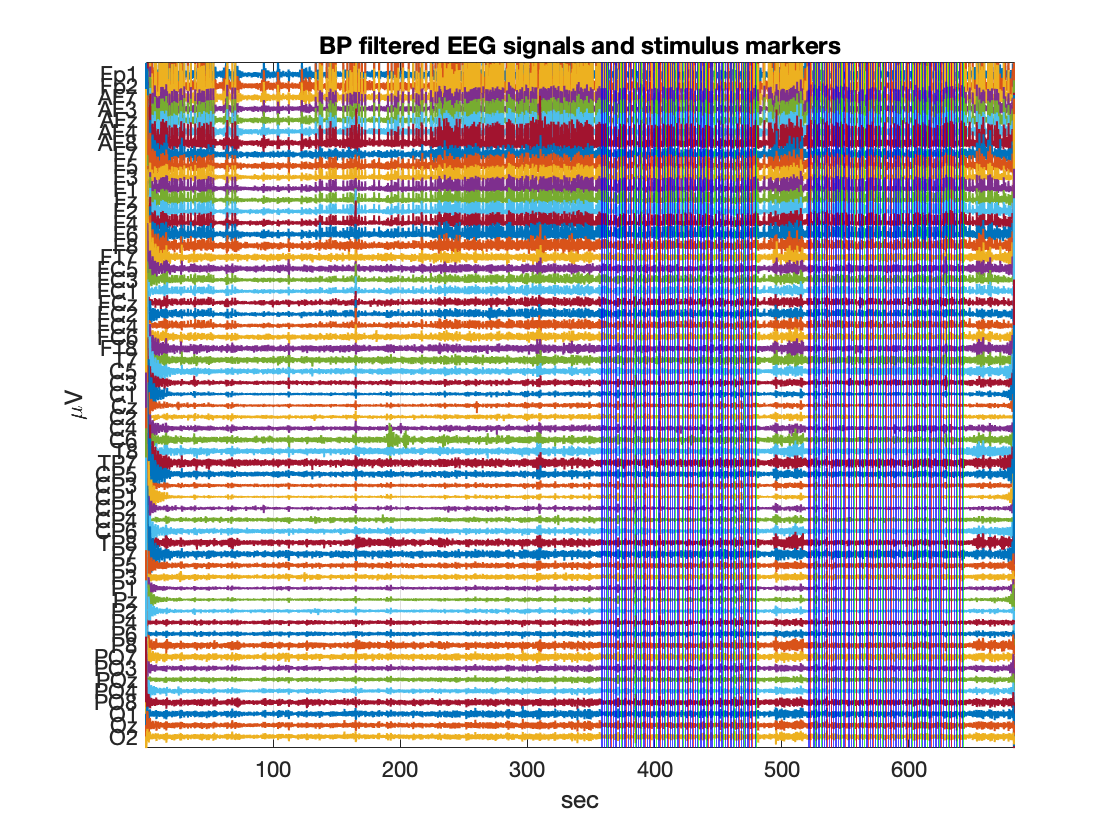

i_stand = find(strcmp(stim_types,'standard'));
i_distr = find(strcmp(stim_types, 'distractor'));
i_targ = find(strcmp(stim_types,'target'));

stim_time = stim_samples/fs;

figure % entire duration
for i = 1:n
    plot(t, X_filt(i,:)-delta*(i-1),'linewidth',1);
    hold on
end

xline(stim_time(i_stand), 'b')
hold on
xline(stim_time(i_distr), 'r')
xline(stim_time(i_targ), 'g')

xlim([t(1) t(end)])
ylim([-delta*n delta])
xlabel('sec')
ylabel('\muV')
title('BP filtered EEG signals and stimulus markers')
set(gca,'ytick',[-delta*(n-1):delta:0])
set(gca,'ytickLabel',fliplr(ch_names))
set(gca,'fontsize',11)
grid

#### Epoching 

It consists in extracting a segment (or epoch) around the time position of each marker of interest, with each epoch containing a pre-event period and a post-event period; all epochs must be of the same length (usually lasting a few tens of milliseconds). After epoching, the extracted epochs can be stored in a 3-D matrix i.e. *electrodes x samples x epochs*.

I am going to extract epochs starting 200 ms before each marker and ending 800 after the marker, for a total duration of 1s.

epoch_lim = [-0.2 0.8];
n_epochs = length(stim_samples);
m_ep=(epoch_lim(2)-epoch_lim(1))*fs;
Xepoched = zeros(n,m_ep,n_epochs);
for i = 1:n_epochs
    lim_left=floor(stim_samples(i)+epoch_lim(1)*fs);
    lim_right=floor(stim_samples(i)+epoch_lim(2)*fs-1) ; 
    Xepoched(:,:,i) = X_filt(:, lim_left:lim_right);
end

Concatenating the epochs along the time dimension, returning back to a 2D matrix. Necessary since ICA conceptually works on that kind of representation.

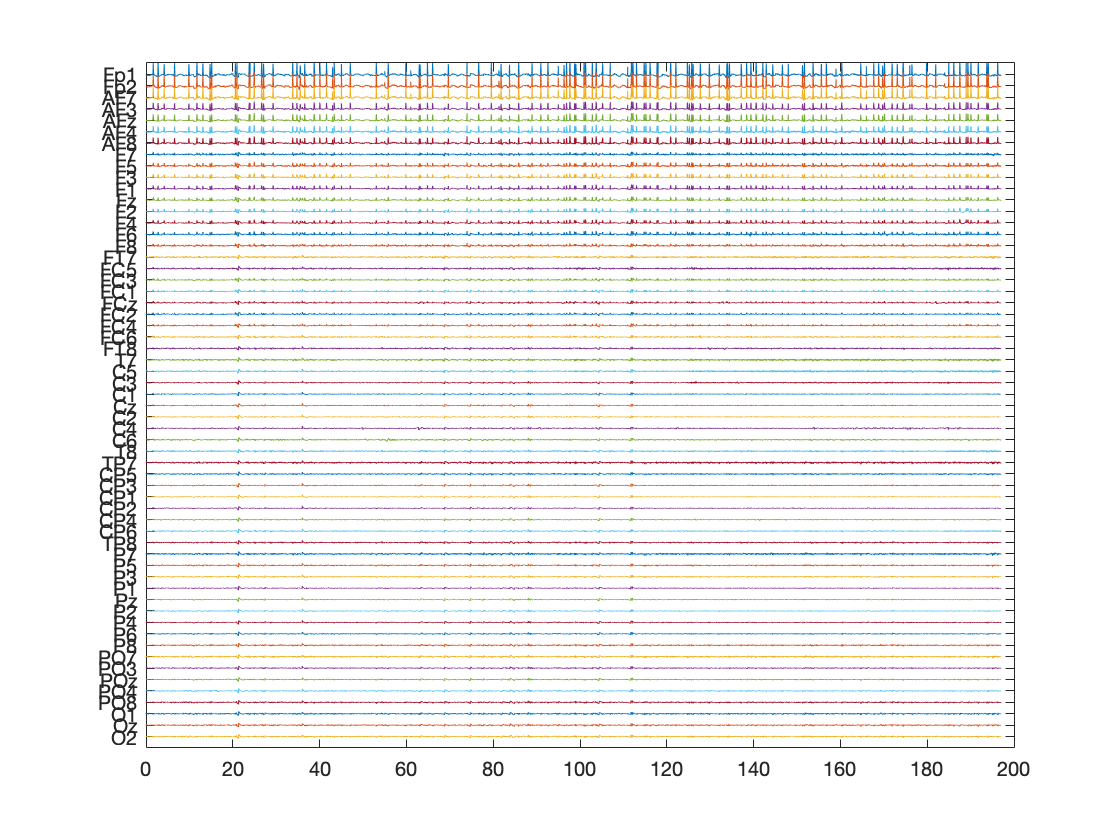

[n, m_ep, n_epochs] = size(Xepoched);
Xep_conc = reshape(Xepoched, n, m_ep*n_epochs);
Xep_samples = 0:m_ep*n_epochs-1;
t_ep = Xep_samples/fs;

delta = 350;
figure
for i = 1:n % for every electrode
    plot(t_ep, Xep_conc(i,:) - delta*(i-1))
    hold on
end
ylim([-delta*n, delta])
set(gca, 'ytick', [-delta*(n-1):delta:0])
set(gca, 'yticklabel', fliplr(ch_names))

#### Bad channels identification

Correlation method: bad channels are identified as those having low correlation (below a given threshold) with the other channels.

RHO = corr(Xep_conc');
rho_j = (1/(n-1)) * (sum(abs(RHO)) - 1);
th = mean(rho_j) - 3*std(rho_j);
index_bad=find(rho_j < th);

ch_names_bad=ch_names(index_bad)


ch_names_bad =

  1×0 empty cell array



No bad channels identified

### Preprocessing 2 

#### Independent component analysis (EEGLAB fun runica.m)

% %%%% comment from here to...(see below) after first use
% rate=0.00065/log(n); %=1.5941e-04 heuristic, suggested as DEFAULT-RATE in runica; the GUI use lrate=0.001
% [weights,sphere]=runica(Xep_conc,'lrate',rate,'extended',1,'bias','off','rndreset','no');
% W = weights*sphere;
% winv=inv(W);
% 
% %Sorting components in descending order of mean projected variance ...
% meanvar = sum(winv.^2).*sum(transpose(W*Xep_conc(:,:)).^2)/(n*m-1);
% [~, windex] = sort(meanvar);
% windex = windex(end:-1:1); % order large to small
% meanvar = meanvar(windex);
% weights = weights(windex,:);
% winv    = inv( weights*sphere );
% 
% %Scaling components
% scaling = repmat(sqrt(mean(winv.^2))', [1 size(weights,2)]);
% weights_new = weights .* scaling;
% W_new=weights_new*sphere;
% A=inv(W_new);
% 
% save matrixW_matrixA_sub003 W_new A
% %%%% finish comment here

load matrixW_matrixA_sub003
S=W_new*Xep_conc;  % Y are the Independent Components


window = 5 * fs; 
NFFT = 2*window;


max_frame = 49250

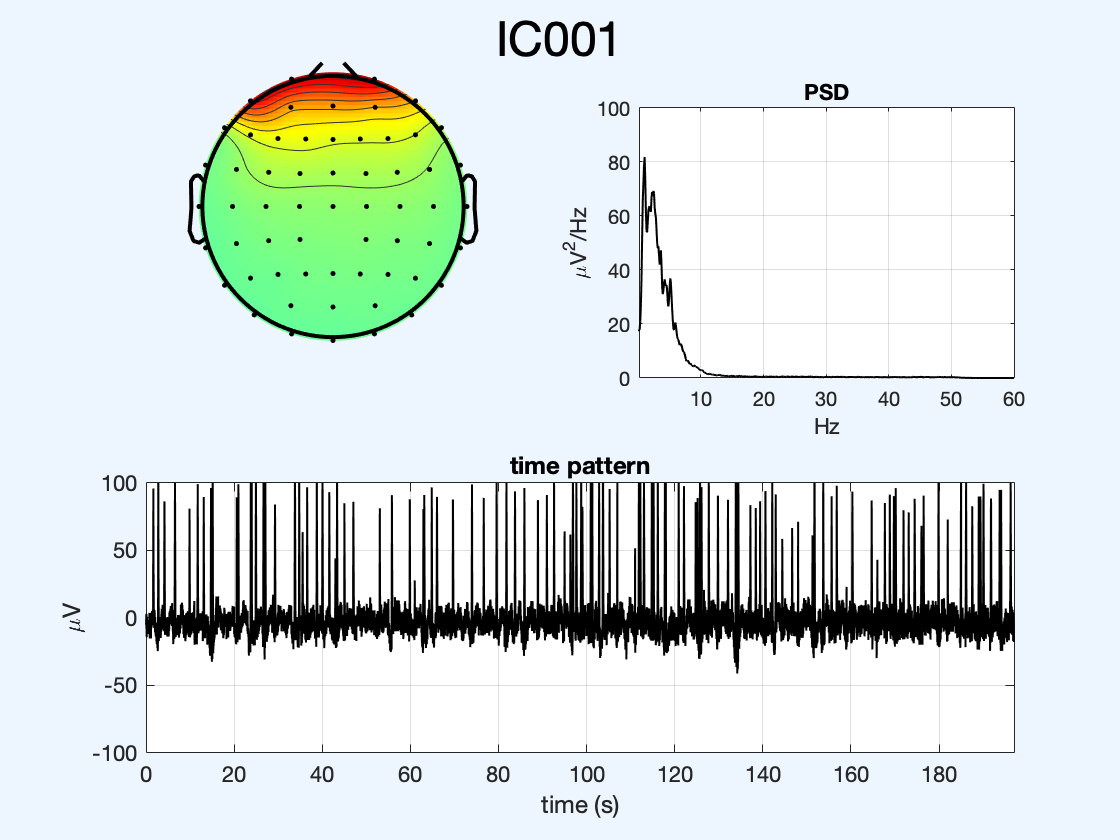

max_frame = 49250

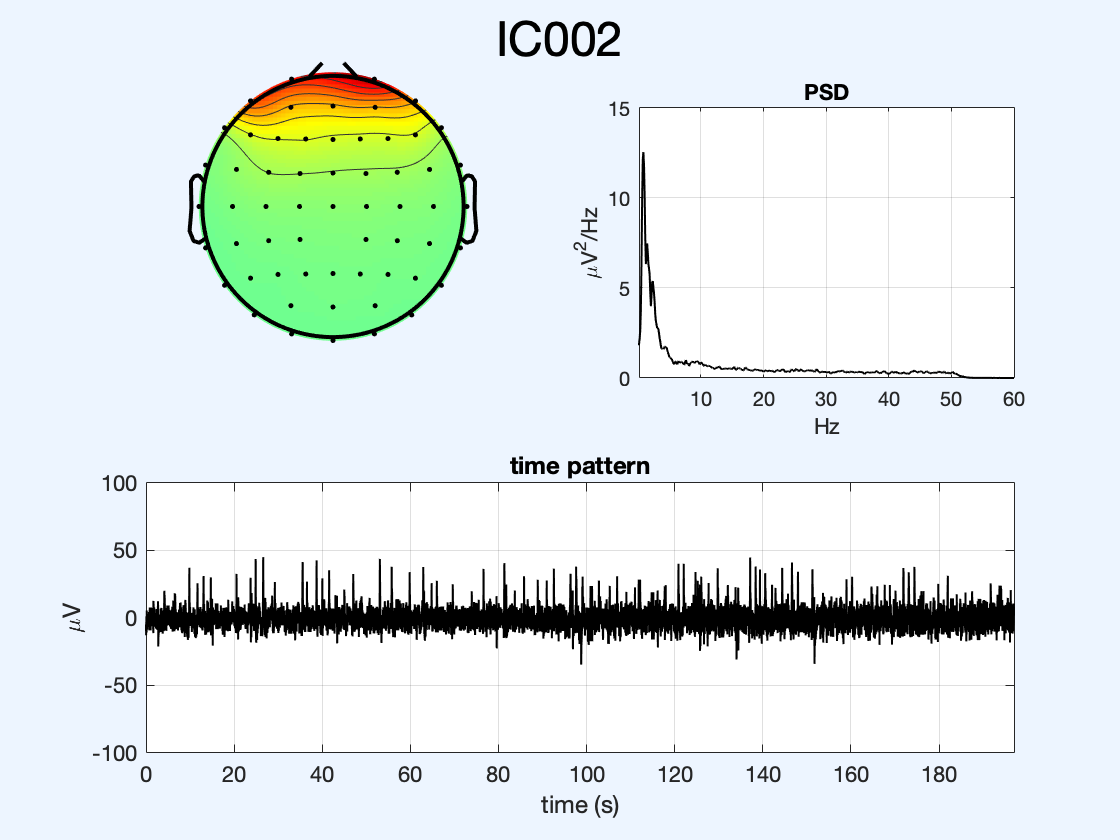

max_frame = 49250

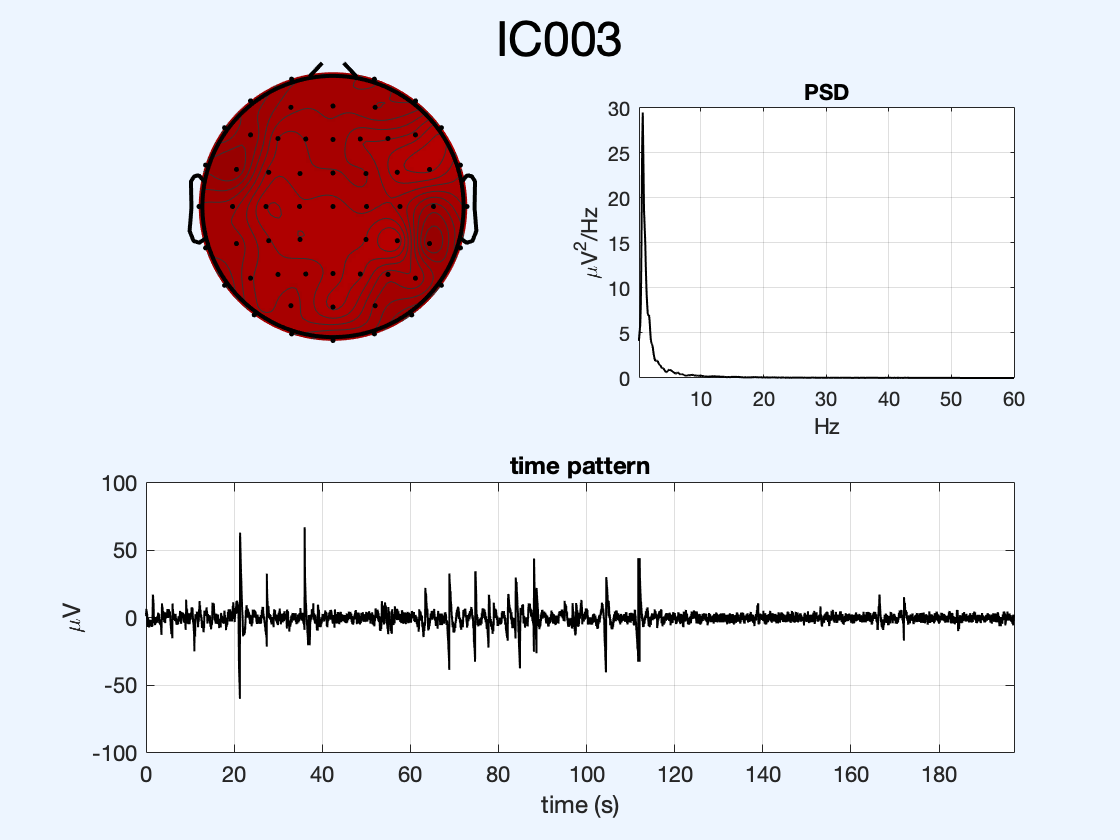

max_frame = 49250

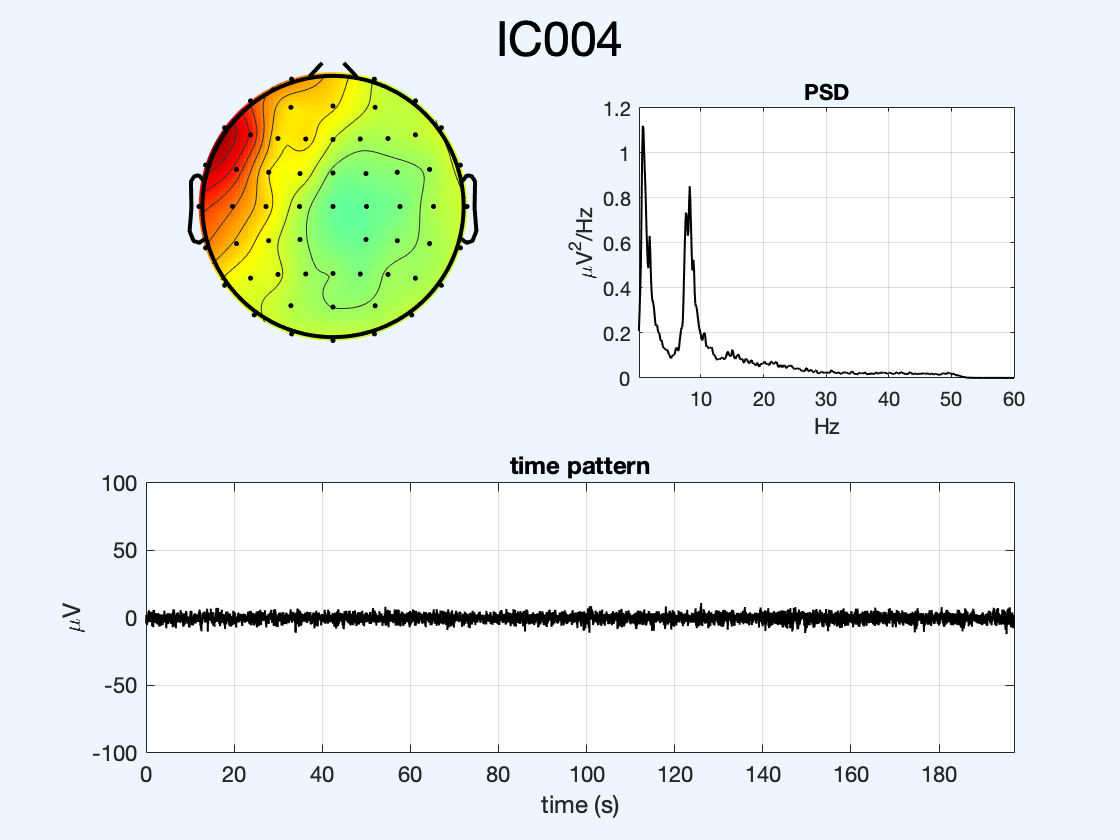

max_frame = 49250

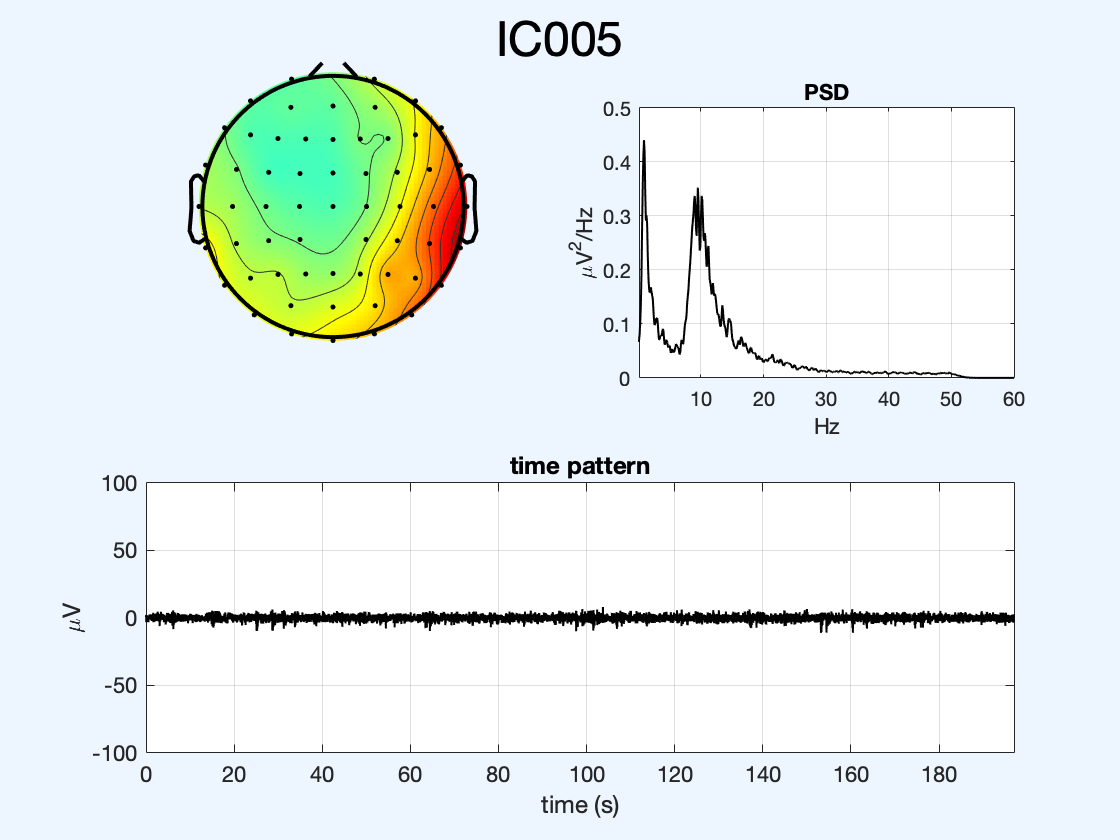

[PSD_IC, f] = pwelch(S', window, [], NFFT, fs); %[] -> 50% overlap between segments
for i = 1:5 % 6:10 11:15 16:20 21:25
    figure
    plot_IC(i, A, S, PSD_IC, f, locs, fs, t_ep(1), t_ep(end));
end

IC1 and IC2 blink artifact ---- IC3 artifact on all electrodes (or on the reference electrode)

IC8 seems to contain frontal EMG artifact 

IC12 strange topographic map (may be electrode artifact and/or EOG artifact) 

IC17 and IC19 clear EMG artifact due to activation of small muscle fibers (highly localized)

IC22 and IC26 electrode pop 

S_new = S; 
ix_to_be_removed = [1,2,3,8,12,17,19,22,26];
S_new(ix_to_be_removed, :) = 0; % putting to 0 the rows corresponding to the artifacts
X_new = A*S_new;  

#### Average re-referencing 

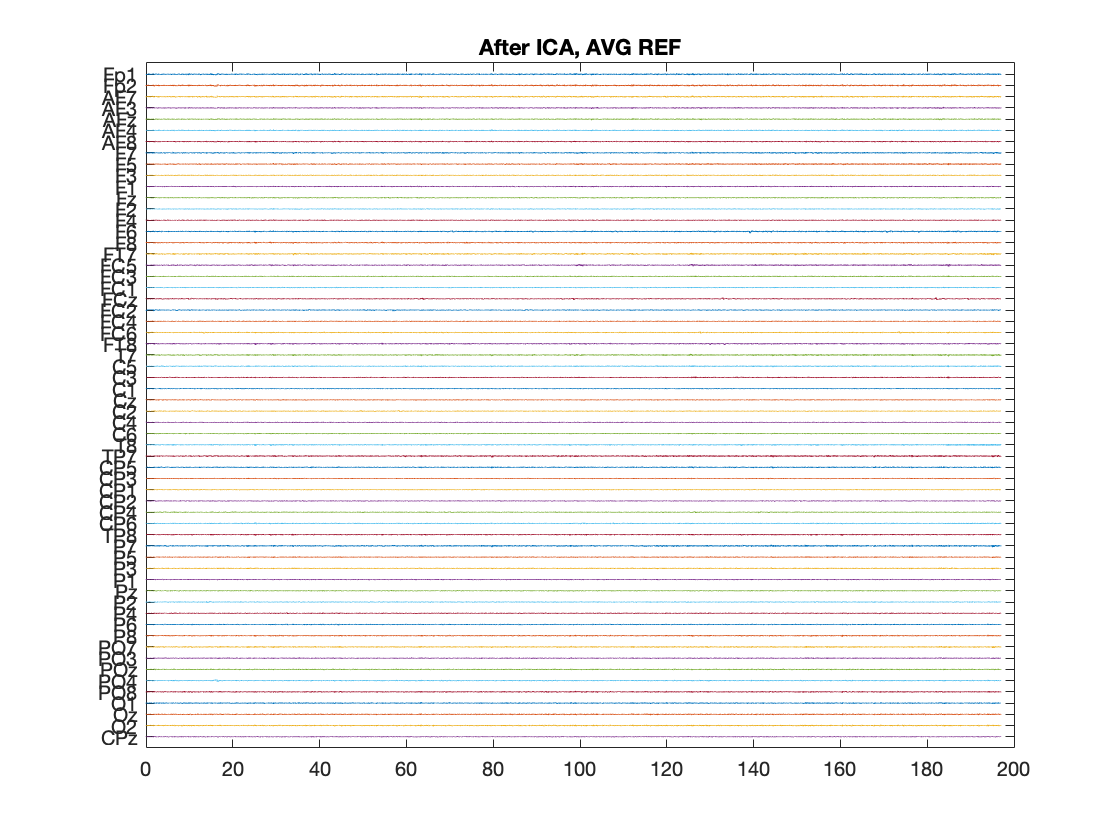

%60 channels, the last row contains CPz referred to AR
[n,m] = size(X_new);
H = eye(n+1) - (1/(n+1)) * ones(n+1,n+1);
X_p = [X_new; zeros(1, m)];
X_AR = H * X_p;

%update the locs structure containing the locations of channels, so to have
%CPz and its location in the last row
ch_names=[ch_names 'CPz'];
idx_CPz = find(strcmp(ch_names_in_locs,'CPz'));
locs(end+1) = default_locs(idx_CPz);

X = X_AR; %resampled, filtered, epoched, concatenated, 
% ICA on good chns and cleaned from artifacts,
% averaged reference and in last row recovered online reference

figure
for i = 1:n+1 % for every electrode
    plot(t_ep, X(i,:) - delta*(i-1))
    hold on
end
ylim([-delta*(n+1), delta])
set(gca, 'ytick', [-delta*(n):delta:0])
set(gca, 'yticklabel', fliplr(ch_names))
title('After ICA, AVG REF')

### ERP analysis

#### Baseline correction

Consists in removing from each epoch the mean value of the signal over a baseline pre-event period. Useful to counteract baseline differences between data epochs (e.g., those arising from low-frequency drifts).

X_epoched = reshape(X_AR, [n+1, m_ep, n_epochs]);
base_ix = 1:51; % indeces of the baseline period from -200 ms to 0 ms
baseline = mean(X_epoched(:,base_ix,:),2); % n x 1 x q 
X_epoched = X_epoched-repmat(baseline,1,m_ep,1); % baseline corrected

#### Separating the epochs according to the type of stimulus 

q_stand = length(i_stand); % number of epochs with standard stimulus
X_epoched_stand = X_epoched(:,:,i_stand);

q_dist = length(i_distr); % number of epochs with standard stimulus
X_epoched_dist = X_epoched(:,:,i_distr);

q_targ = length(i_targ); % number of epochs with standard stimulus
X_epoched_targ = X_epoched(:,:,i_targ);

#### Averaging technique

Consists in computing, in each time instant inside the epoch, the average value across the epochs. Done to increase the signal to noise ratio. (Signal: evoked response. Noise: background EEG activity)

WSA_stand = mean(X_epoched_stand, 3);
WSA_targ = mean(X_epoched_targ, 3);
WSA_dist = mean(X_epoched_dist, 3);

Plot

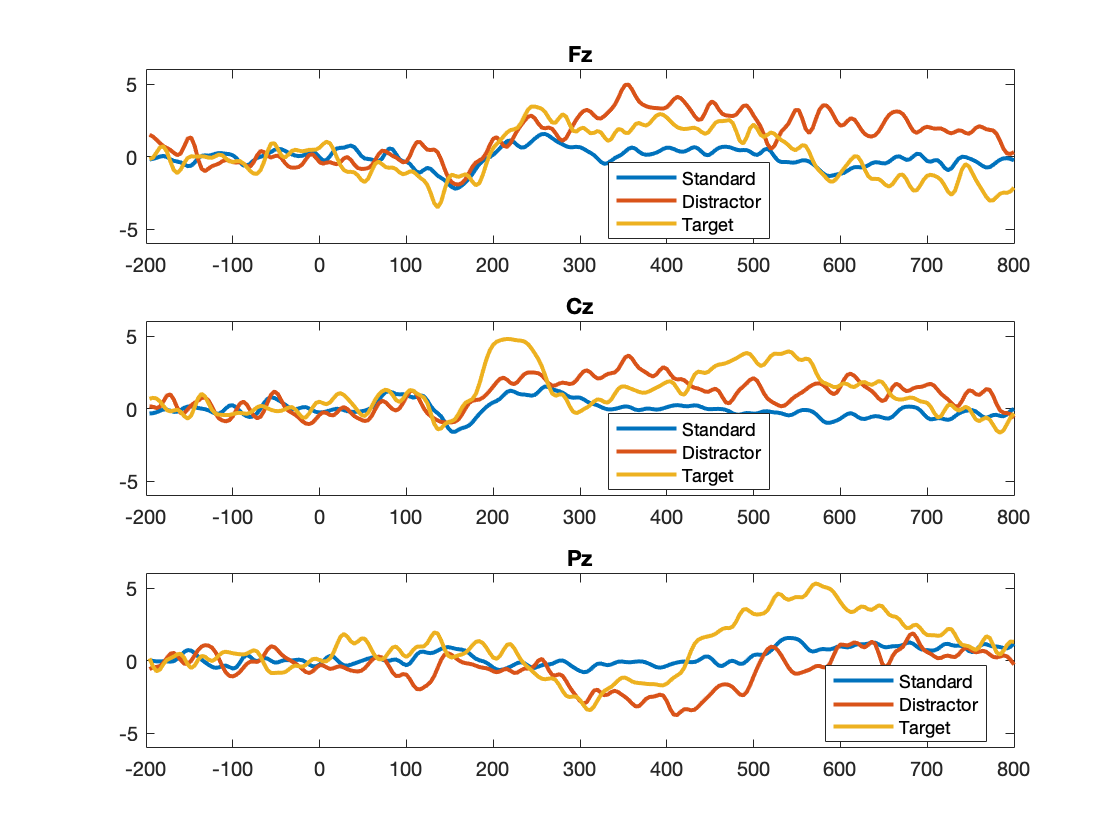

t = [1:m_ep]/fs;

ix_Fz= find(strcmp(ch_names,'Fz'));
ix_Cz= find(strcmp(ch_names,'Cz'));
ix_Pz= find(strcmp(ch_names,'Pz'));

figure

subplot(311)
plot(t, WSA_stand(ix_Fz,:), 'LineWidth', 2)
hold on
plot(t, WSA_dist(ix_Fz,:), 'LineWidth', 2)
plot(t, WSA_targ(ix_Fz,:), 'LineWidth', 2)
legend('Standard', 'Distractor', 'Target', 'Location', 'best')
title('Fz')
xticklabels([-200:100:800])
ylim([-6 +6])

subplot(313)
plot(t, WSA_stand(ix_Pz,:), 'LineWidth', 2)
hold on
plot(t, WSA_dist(ix_Pz,:), 'LineWidth', 2)
plot(t, WSA_targ(ix_Pz,:), 'LineWidth', 2)
legend('Standard', 'Distractor', 'Target', 'Location', 'best')
title('Pz')
xticklabels([-200:100:800])
ylim([-6 +6])

subplot(312)
plot(t, WSA_stand(ix_Cz,:), 'LineWidth', 2)
hold on
plot(t, WSA_dist(ix_Cz,:), 'LineWidth', 2)
plot(t, WSA_targ(ix_Cz,:), 'LineWidth', 2)
legend('Standard', 'Distractor', 'Target', 'Location', 'best')
title('Cz')
xticklabels([-200:100:800])
ylim([-6 +6])

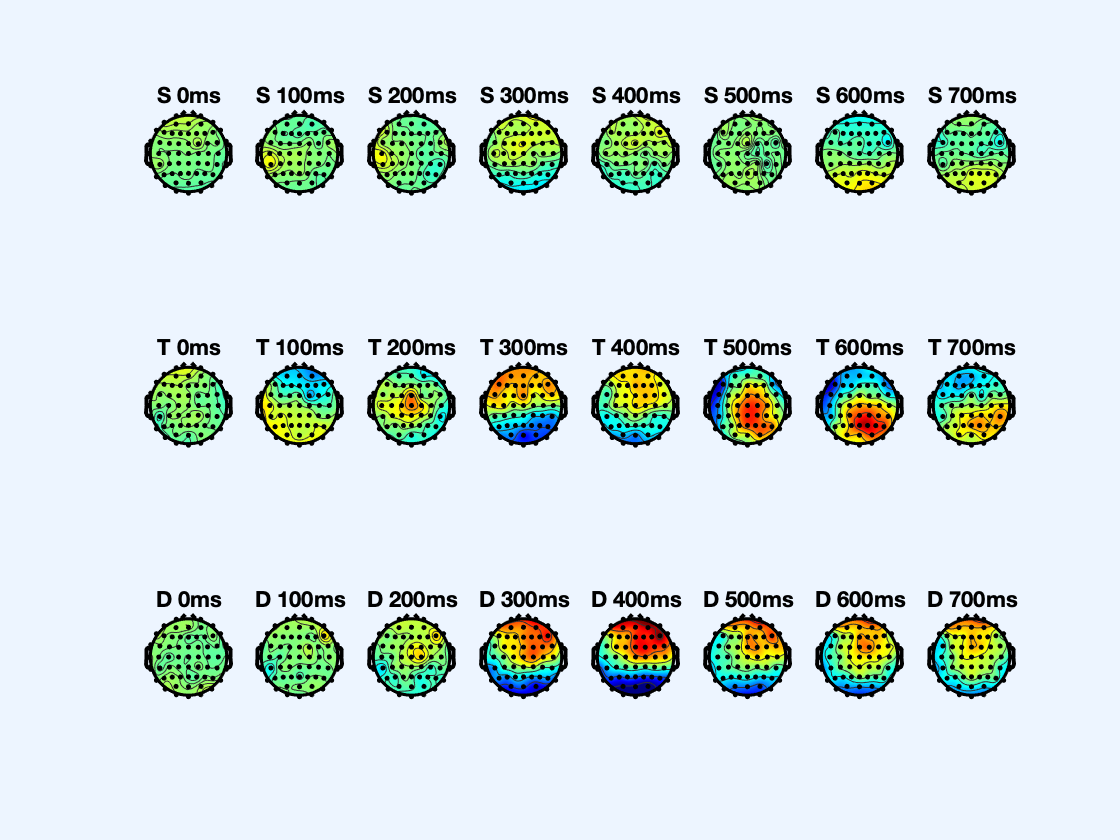

map_frames = [0.2:0.1:0.9]*fs;
n_cond = 3;
titles = {'0ms', '100ms', '200ms', '300ms', ...
     '400ms', '500ms', '600ms', '700ms'};
n_maps = length(map_frames);
figure

for j = 1:n_maps
    start = floor(map_frames(j) - 0.05*fs);
    stop = floor(map_frames(j) + 0.05*fs);
    time_avg_WSA_stand = mean(WSA_stand(:, start:stop), 2);
    subplot(n_cond, n_maps, j)
    topoplot(time_avg_WSA_stand, locs, 'maplimits', [-5 5]);
    title(['S ', titles{j}])
end

for j = 1:n_maps
    start = floor(map_frames(j) - 0.05*fs);
    stop = floor(map_frames(j) + 0.05*fs);
    time_avg_WSA_targ = mean(WSA_targ(:, start:stop), 2);
    subplot(n_cond, n_maps, j+8)
    topoplot(time_avg_WSA_targ, locs, 'maplimits', [-5 5]);
    title(['T ',titles{j}])
end

for j = 1:n_maps
    start = floor(map_frames(j) - 0.05*fs);
    stop = floor(map_frames(j) + 0.05*fs);
    time_avg_WSA_dist = mean(WSA_dist(:, start:stop), 2);
    subplot(n_cond, n_maps, j+16)
    topoplot(time_avg_WSA_dist, locs, 'maplimits', [-5 5]);
    title(['D ',titles{j}])
end

The ERP waveform associated to the target stimulus displays P300, which is maximal over the parietal and central electrodes, while the P300 is not present in the ERP waveform associated to the standard stimulus. The P3 peak has been associated to voluntary attentional components, recognition of stimulus relevance for the task, and memory updating. 	The P3 evoked by this two-stimulus oddball task is often referred to as P3b, in order to distinguish it from a variant, called P3a.	

The latter appears when a third ‘novel’ (still rare) stimulus is inserted into the oddball task, and the subject is not required to respond to this stimulus (also called ‘distractor’). ‘Novelty’ refers to the context of the other two stimuli. Such novel stimuli elicit a large positivity (P3a) with a latency that is earlier than that of the target-evoked P3b, and a scalp distribution that is more oriented towards the front of the scalp. P3a has been linked to involuntary capture of attention 

### Time-frequency analysis - Wavelet Transform

fmin = 3.125;
fmax = 50;
flimits = [fmin, fmax];
for i=1:n
    for j=1:q_stand
        [C,F] = cwt(X_epoched_stand(i,:,j),'amor',fs,'frequencylimits',flimits);
        CPower_epoch_stand(:,:,j) = abs(C).^2; %contains the Cpower for the same channel at different epochs
    end
    CPower_mean_stand(:,:,i)=mean(CPower_epoch_stand,3); %contains the Cpower for different channels averaged across epochs
end

for i=1:n
    for j=1:q_targ
        [C,F] = cwt(X_epoched_targ(i,:,j),'amor',fs,'frequencylimits',flimits);
        CPower_epoch_targ(:,:,j) = abs(C).^2; %contains the Cpower for the same channel at different epochs
    end
    CPower_mean_targ(:,:,i)=mean(CPower_epoch_targ,3); %contains the Cpower for different channels averaged across epochs
end

for i=1:n
    for j=1:q_dist
        [C,F] = cwt(X_epoched_dist(i,:,j),'amor',fs,'frequencylimits',flimits);
        CPower_epoch_dist(:,:,j) = abs(C).^2; %contains the Cpower for the same channel at different epochs
    end
    CPower_mean_dist(:,:,i)=mean(CPower_epoch_dist,3); %contains the Cpower for different channels averaged across epochs
end

% along the pages: I have the channels!!!!

Normalizing the power in order to appreciate ERS and ERD

baseidx=[1 51]; % indeces of the baseline period from -200 ms to 0 ms 
baselineC_stand=mean(CPower_mean_stand(:,baseidx(1):baseidx(2),:),2); 
CPower_stand=CPower_mean_stand./(repmat(baselineC_stand,1,m_ep,1));

baselineC_targ=mean(CPower_mean_targ(:,baseidx(1):baseidx(2),:),2); 
CPower_targ=CPower_mean_targ./(repmat(baselineC_targ,1,m_ep,1));

baselineC_dist=mean(CPower_mean_dist(:,baseidx(1):baseidx(2),:),2); 
CPower_dist=CPower_mean_dist./(repmat(baselineC_dist,1,m_ep,1));

Scalogram

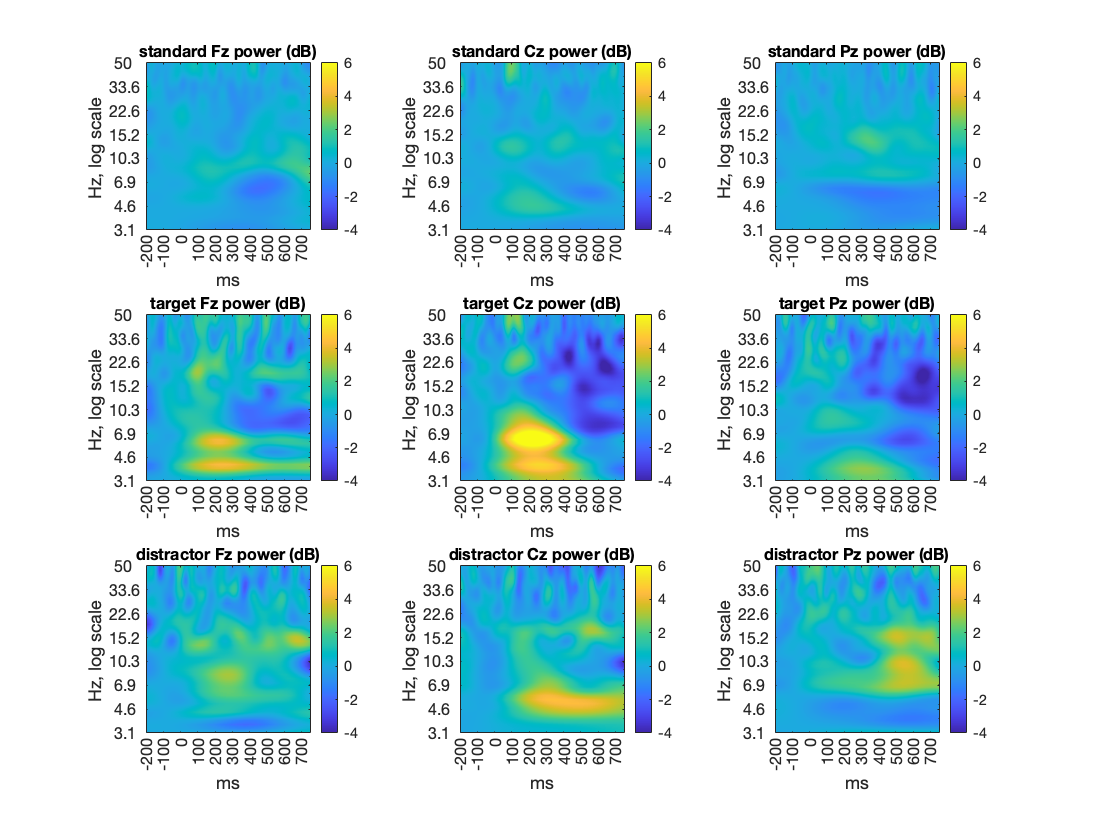

time_values=[(0:1:m_ep-1)/fs]*1000-200; %time axis from -200 ms to 800 ms 
frequency_values=F; %frequency axis obtained from cwt
clim=[-4 6];
figure
subplot(331)
title_string=['standard ', ch_names{12}];
TF_colormap(time_values,frequency_values, CPower_stand(:,:,12),clim,title_string)
subplot(332)
title_string=['standard ', ch_names{30}];
TF_colormap(time_values,frequency_values, CPower_stand(:,:,30),clim,title_string)
subplot(333)
title_string=['standard ', ch_names{47}];
TF_colormap(time_values,frequency_values, CPower_stand(:,:,47),clim,title_string)
subplot(334)
title_string=['target ', ch_names{12}];
TF_colormap(time_values,frequency_values, CPower_targ(:,:,12),clim,title_string)
subplot(335)
title_string=['target ', ch_names{30}];
TF_colormap(time_values,frequency_values, CPower_targ(:,:,30),clim,title_string)
subplot(336)
title_string=['target ', ch_names{47}];
TF_colormap(time_values,frequency_values, CPower_targ(:,:,47),clim,title_string)
subplot(337)
title_string=['distractor ', ch_names{12}];
TF_colormap(time_values,frequency_values, CPower_dist(:,:,12),clim,title_string)
subplot(338)
title_string=['distractor ', ch_names{30}];
TF_colormap(time_values,frequency_values, CPower_dist(:,:,30),clim,title_string)
subplot(339)
title_string=['distractor ', ch_names{47}];
TF_colormap(time_values,frequency_values, CPower_dist(:,:,47),clim,title_string)

TARGET STIMULUS: ERS in the theta band at 100-400 ms in the frontal end especially in the central regions, and ERD in the alpha and theta band at 400-700 ms especially in frontal and posterior regions

DISTRACTOR: ERS in the theta band at 200-700 ms in the central regions